# Annotation Bounding Boxes

## Scenario setup

% Link bng object to BeamNG folder.
% beamng = py.beamngpy.BeamNGpy('localhost', int32(64256), home='/path/to/BeamNG.drive');
beamng = py.beamngpy.BeamNGpy('localhost', int32(64256));
beamng.open();                                                       % Start up the simulator.
scenario = py.beamngpy.Scenario('italy', 'annotation_bounding_boxes');      % Create the scenario.
%
% Create some vehicles which will appear in the camera images.
ego = py.beamngpy.Vehicle('ego', pyargs('model', 'etk800', 'color', 'White'));
scenario.add_vehicle(ego, pyargs('pos', py.list({237.90, -894.42, 246.10}), 'rot_quat', py.list({0.0173, -0.0019, -0.6354, 0.7720})));
car1 = py.beamngpy.Vehicle('car1', pyargs('model', 'etk800', 'color', 'Green'));
scenario.add_vehicle(car1, pyargs('pos', py.list({246.94, -901.64, 247.58}), 'rot_quat', py.list({-0.0099, 0.0206, 0.9348, -0.3543})));
car2 = py.beamngpy.Vehicle('car2', pyargs('model', 'etk800', 'color', 'Red'));
scenario.add_vehicle(car2, pyargs('pos', py.list({276.27, -881.42, 247.84}), 'rot_quat', py.list({-0.0106, 0.0405, 0.4845, 0.8738})));
car3 = py.beamngpy.Vehicle('car3', pyargs('model', 'etki', 'color', 'Blue'));
scenario.add_vehicle(car3, pyargs('pos', py.list({261.52, -894.68, 248.04}), 'rot_quat', py.list({0.0026, 0.01758, -0.8344, 0.5508})));
car4 = py.beamngpy.Vehicle('car4', pyargs('model', 'miramar', 'color', 'Black'));
scenario.add_vehicle(car4, pyargs('pos', py.list({267.06, -892.03, 248.32}), 'rot_quat', py.list({0.0065, 0.0194, -0.8501, 0.5262})));

scenario.make(beamng);
beamng.set_deterministic();
beamng.set_steps_per_second(int32(60));                           % Set simulator to 60hz temporal resolution
beamng.load_scenario(scenario);
beamng.hide_hud();

## Run simulation

beamng.start_scenario();
beamng.switch_vehicle(ego);

% Get the annotation class data.
annotations = beamng.camera.get_annotations();                    % Gets a dictionary of RGB colours, indexed by material names.
disp(annotations);

  Python dict with no properties.

    {'COBBLESTONE': (32, 64, 196), 'STREET': (255, 0, 0), 'SIDEWALK': (89, 118, 155), 'ASPHALT': (128, 128, 128), 'MUD': (128, 96, 32), 'POLE': (168, 193, 201), 'BACKGROUND': (16, 16, 16), '': (0, 0, 0), 'DASHED_LINE': (196, 196, 255), 'NATURE': (128, 255, 128), 'CAR': (0, 255, 0), 'SIDEBARS': (31, 74, 214), 'GUARD_RAIL': (0, 128, 128), 'TRAFFIC_SIGNS': (255, 0, 128), 'SAND': (255, 196, 32), 'ZEBRA_CROSSING': (255, 128, 128), 'TRAFFIC_SIGNALS': (255, 128, 0), 'TRUCK_TRAILERS': (64, 196, 64), 'OBSTACLES': (0, 196, 196), 'SOLID_LINE': (255, 196, 128), 'BUILDINGS': (255, 196, 196), 'SPEED_BUMP': (196, 64, 64), 'RESTRICTED_STREET': (196, 0, 0), 'WATER': (25, 25, 255), 'GRASS': (64, 128, 64), 'DRIVING_INSTRUCTIONS': (132, 226, 244), 'TRUCK': (0, 255, 128), 'SKY': (128, 196, 255), 'ROADBLOCK': (64, 0, 0), 'ROCK': (96, 96, 96)}



class_data = beamng.camera.get_annotation_classes(annotations);   % Gets a dictionary of material names, indexed by RGB colours (encoded as 32-bit).
disp(class_data);

  Python dict with no properties.

    {2113732: 'COBBLESTONE', 16711680: 'STREET', 5863067: 'SIDEWALK', 8421504: 'ASPHALT', 8413216: 'MUD', 11059657: 'POLE', 1052688: 'BACKGROUND', 0: '', 12895487: 'DASHED_LINE', 8454016: 'NATURE', 65280: 'CAR', 2050774: 'SIDEBARS', 32896: 'GUARD_RAIL', 16711808: 'TRAFFIC_SIGNS', 16761888: 'SAND', 16744576: 'ZEBRA_CROSSING', 16744448: 'TRAFFIC_SIGNALS', 4244544: 'TRUCK_TRAILERS', 50372: 'OBSTACLES', 16761984: 'SOLID_LINE', 16762052: 'BUILDINGS', 12861504: 'SPEED_BUMP', 12845056: 'RESTRICTED_STREET', 1645055: 'WATER', 4227136: 'GRASS', 8708852: 'DRIVING_INSTRUCTIONS', 65408: 'TRUCK', 8439039: 'SKY', 4194304: 'ROADBLOCK', 6316128: 'ROCK'}



pause(int32(10));                                              % Some sleeping time to make sure the level is fully loaded.

% Create some camera sensors in the simulation.
disp('Camera test start.');

Camera test start.



% Create a camera sensor.
cam_width = 1024;
cam_height = 1024;

args = pyargs( ...
            'requested_update_time', -1.0, ...
            'is_using_shared_memory', false, ...
            'pos', py.list({-0.3, 1.0, 2.0}), ...
            'dir', py.list({0, -1.0, 0.0}), ...
            'field_of_view_y' , 70 , ...
            'near_far_planes' ,  py.list({0.1, 100}), ... 
            'resolution', py.list({int32(cam_width), int32(cam_height)}), ...
            'is_render_annotations', true, ...
            'is_render_instance', true, ...
            'is_render_depth', true);

cam1 = py.beamngpy.sensors.Camera('camera1', beamng, ego, args);

% Wait a couple of seconds (to give camera sensor time to update) then poll it.
pause(2);
images = cam1.get_full_poll_request();

## Plot results

% Plot the camera images.
subplot 231
colour_RGBA = double(py.numpy.array(images{'colour'}));
colour_RGB = colour_RGBA(:, :, 1:3) / 256;
image(colour_RGB);
title('Colour');
axis equal
xlim([0 cam_width])
ylim([0 cam_height])

subplot 232
annotation_RGBA = double(py.numpy.array(images{'annotation'}));
annotation_RGB = annotation_RGBA(:, :, 1:3) / 256;
image(annotation_RGB);
title('Class Annotations');
axis equal
xlim([0 cam_width])
ylim([0 cam_height])

subplot 233
instance_RGBA = double(py.numpy.array(images{'instance'}));
instance_RGB = instance_RGBA(:, :, 1:3) / 256;
image(instance_RGB);
title('Instance Annotations');
axis equal
xlim([0 cam_width])
ylim([0 cam_height])

subplot 234
depth_RGB = double(py.numpy.array(images{'depth'}));
image(depth_RGB);
colormap(gray)
title('Depth');
axis equal
xlim([0 cam_width])
ylim([0 cam_height])

% Compute and display the bounding boxes for each vehicle instance.
bounding_boxes = cam1.extract_bounding_boxes(images{'annotation'}, images{'instance'}, class_data);
for i = bounding_boxes.length - 1 : -1 : 1
    n = bounding_boxes(i);
    disp(n{1}{'class'})
    if n{1}{'class'} ~= "CAR"
        bounding_boxes.remove(n{1});
    end
end

  Python str with no properties.

    NATURE

  Python str with no properties.

    SKY



disp(bounding_boxes);

  Python list with values:

    [{'bbox': [98, 506, 330, 536], 'class': 'ASPHALT', 'color': [128, 128, 128, 255]}]

    Use string, double or cell function to convert to a MATLAB array.



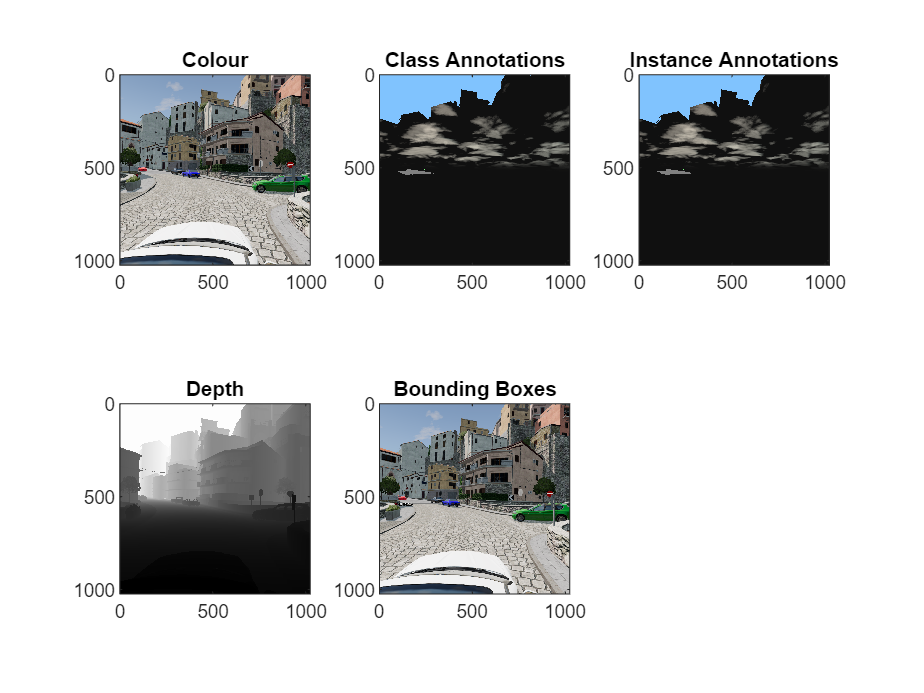


% Draw the bounding boxes on top of the colour image.
image_with_boxes = cam1.draw_bounding_boxes(bounding_boxes, images{'colour'});
subplot 235
image_with_boxes_RGBA = double(py.numpy.array(image_with_boxes));
image_with_boxes_RGB = image_with_boxes_RGBA(:, :, 1:3) / 256;
image(image_with_boxes_RGB);
title('Bounding Boxes');
axis equal
xlim([0 cam_width])
ylim([0 cam_height])


% Export the bounding boxes to PASCAL-VOC XML format.
xml = cam1.export_bounding_boxes_xml(bounding_boxes, pyargs('filename', 'example.png', ...
                                                            'size', py.list({cam_width, cam_height, 3})));
disp(xml);

  Python str with no properties.

    <?xml version="1.0" ?>
    <annotation>
      <filename>example.png</filename>
      <size>
        <width>1024.0</width>
        <height>1024.0</height>
        <depth>3.0</depth>
      </size>
      <segmented>0</segmented>
      <object>
        <name>ASPHALT_0</name>
        <pose>Unspecified</pose>
        <truncated>0</truncated>
        <difficult>0</difficult>
        <bndbox>
          <xmin>98</xmin>
          <ymin>506</ymin>
          <xmax>330</xmax>
          <ymax>536</ymax>
        </bndbox>
      </object>
    </annotation>
    




% Close the simulation.
beamng.close();